load mtlb;
X = resample(mtlb,44100,Fs);
Fs = 44100;
X = [[X X];zeros(1*Fs,2)]./max(X,[],"all")/2;

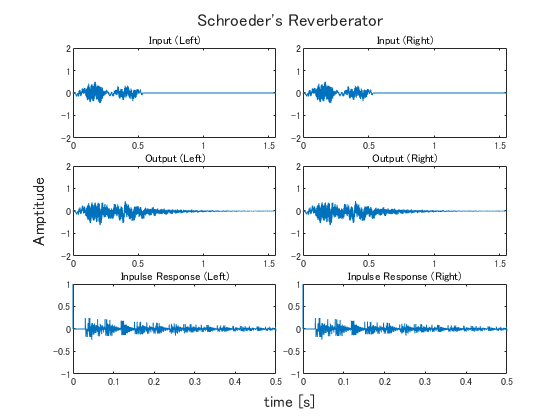

p = CR_Schroeders();

p.T      = 2;
p.drymix = 1;
p.wetmix = 0.5;

test_reverb(p, X, Fs);

p = CR_Moorers();

エラー: CR_Moorers
ファイル: CR_Moorers.m、行: 67、列: 96
式が無効です。関数の呼び出しまたは変数のインデックス付けにはかっこを使用してください。そうでない場合、区切り記号の不一致をチェックしてください。


p.T      = 7.44;
p.drymix = 1;
p.wetmix = 0.5;

test_reverb(p, X, Fs);

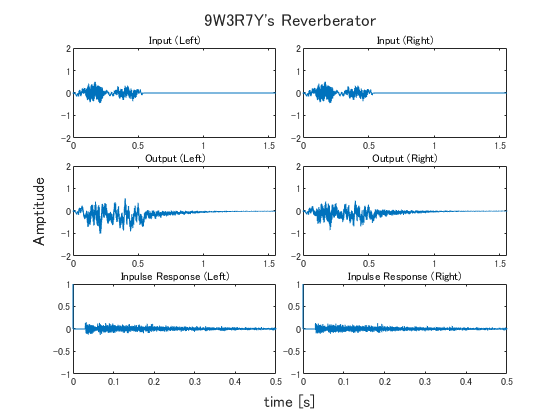

p = Q_Reverb();
p.T      = 2;
p.drymix = 1;
p.wetmix = 0.5;
p.W      = 0.34;

test_reverb(p, X, Fs);

function [X, Y] = test_plugin(p, X, Fs)
    p.Fs = Fs;

    BFSIZE = 1024;
    
    nloop = floor(length(X)/BFSIZE)+1;
    X((nloop)*BFSIZE,:) = [0;0];
    
    % output matrix
    Y = zeros(size(X));
    
    % main loop
    for i = 1:nloop
        % read buffer
        idxs = ((i-1)*BFSIZE+1):(i*BFSIZE);
        in = X(idxs,:);
        
        % process
        out = p.process(in);
        
        Y(idxs,:) = out;
    end
end

function test_reverb(p, X, Fs)
    Impulse = zeros(size(X));
    Impulse(1,:) = [1 1];
    
    [X, Y] = test_plugin(p,X,Fs);
    T = ((1:length(X))-1)/Fs;figure;t = tiledlayout(3,2,"TileSpacing","tight");
    
    p.resetBuffers();
    p.wetmix = 1;
    [~, Resp] = test_plugin(p,Impulse,Fs);
    
    
    nexttile;plot(T,X(:,1));
    subtitle("Input (Left)");xlim([-inf,inf]);ylim([-2,2]);
    
    nexttile;plot(T,X(:,2));
    subtitle("Input (Right)");xlim([-inf,inf]);ylim([-2,2]);
    
    nexttile;plot(T,Y(:,1));
    subtitle("Output (Left)");xlim([-inf,inf]);ylim([-2,2]);
    
    nexttile;plot(T,Y(:,2));
    subtitle("Output (Right)");xlim([-inf,inf]);ylim([-2,2]);
    
    nexttile;plot(T,Resp(:,1));
    subtitle("Inpulse Response (Left)");xlim([0,0.5]);ylim([-1,1]);
    
    nexttile;plot(T,Resp(:,2));
    subtitle("Inpulse Response (Right)");xlim([0,0.5]);ylim([-1,1]);
    
    title(t,p.name);xlabel(t,"time [s]");ylabel(t,"Amptitude");
    
    % sound
    sound(X,Fs);
    pause(1);
    sound(Y,Fs);
end